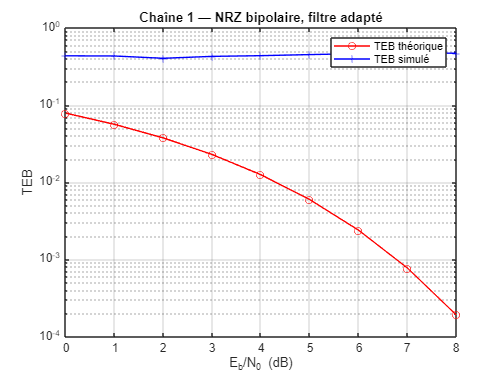

clear all
close all

% =========================================================
%  PARAMÈTRES COMMUNS AUX 3 CHAÎNES
% =========================================================
Fe = 24000;           % Fréquence d'échantillonnage (Hz)
Rb = 6000;            % Débit binaire (bits/s)
Ns = Fe / Rb;         % Facteur de suréchantillonnage = 4
N_bit_block = 1000;   % Nombre de bits par bloc (compromis vitesse/précision)
tab_Eb_sur_N0_dB = 0:8;  % Valeurs de Eb/N0 testées (en dB)


% =========================================================
%  CHAÎNE 1 — RÉFÉRENCE
%  Modulation : NRZ bipolaire (M=2), filtre adapté au récepteur
%  But : valider que TEB simulé ≈ TEB théorique erfc(sqrt(Eb/N0))
% =========================================================
M1 = 2;               % Ordre de modulation binaire
h1 = ones(1, Ns);     % Filtre émission : porte rectangulaire de durée T=Ns*Te
hr1 = fliplr(h1);     % Filtre réception : filtre ADAPTÉ = retournement temporel
                      % (optimal au sens du SNR en sortie pour bruit blanc)

for indice = 0:length(tab_Eb_sur_N0_dB)-1
    Eb_sur_N0_dB = tab_Eb_sur_N0_dB(indice+1);
    nb_erreurs = 0;
    compteur = 0;
    TEB_cumul = 0;

    while nb_erreurs < 1000   % On accumule jusqu'à 1000 erreurs pour avoir
                              % une estimation statistiquement significative

        % --- ÉMETTEUR ---
        bits = randi([0,1], 1, N_bit_block);
        symboles = 2*bits - 1;                        % Mapping : 0->-1, 1->+1
        diracs = kron(symboles, [1 zeros(1,Ns-1)]);   % Suréchantillonnage
        signal_emis = filter(h1, 1, diracs);          % Filtrage de mise en forme

        % --- CANAL AWGN ---
        Pr = mean(abs(signal_emis).^2);               % Puissance du signal
        Eb_sur_N0 = 10^(Eb_sur_N0_dB / 10);
        % Variance du bruit calculée à partir de Eb/N0 (formule du cours slide 294)
        Pb = (Pr * Ns) / (2 * log2(M1) * Eb_sur_N0);
        bruit = sqrt(Pb) * randn(1, length(signal_emis));
        signal_recu = signal_emis + bruit;

        % --- RÉCEPTEUR ---
        signal_filtre = filter(hr1, 1, signal_recu);  % Filtrage adapté
        t0 = 2*Ns - 1;    % Instant d'échantillonnage optimal (retard du filtre adapté)
        signal_echantillonne = signal_filtre(t0:Ns:end);

        symboles_decides = sign(signal_echantillonne);  % Seuil à 0 pour NRZ bipolaire
        bits_decides = (symboles_decides + 1) / 2;      % Demapping : +1->1, -1->0

        nb = min(length(bits), length(bits_decides));
        nb_erreurs = nb_erreurs + sum(bits(1:nb) ~= bits_decides(1:nb));
        TEB_cumul = TEB_cumul + sum(bits(1:nb) ~= bits_decides(1:nb)) / nb;
        compteur = compteur + 1;
    end

    TEB_simu_chaine1(indice+1) = TEB_cumul / compteur;
end

% TEB théorique chaîne 1 : Q(sqrt(2*Eb/N0)) = 0.5*erfc(sqrt(Eb/N0))
% Valable pour NRZ bipolaire avec filtre adapté et bruit AWGN
tab_Eb_sur_N0 = 10.^(tab_Eb_sur_N0_dB / 10);
TEB_th_chaine1 = 0.5 * erfc(sqrt(tab_Eb_sur_N0));


% =========================================================
%  CHAÎNE 2
%  Modulation : NRZ bipolaire (M=2), filtre réception SOUS-OPTIMAL
%  Filtre réception : porte rectangulaire de durée T/2 (moitié de la durée symbole)
%  But : comparer l'efficacité en puissance avec la chaîne 1
% =========================================================
h2 = ones(1, Ns); % Filtre émission : même porte rectangulaire
hr2 = [ones(1, floor(Ns/2)) zeros(1, ceil(Ns/2))];  % Filtre réception : demi-porte
% Ce filtre N'est PAS adapté -> pertes en SNR par rapport à la chaîne 1

for indice = 0:length(tab_Eb_sur_N0_dB)-1
    Eb_sur_N0_dB = tab_Eb_sur_N0_dB(indice+1);
    nb_erreurs = 0;
    compteur = 0;
    TEB_cumul = 0;

    while nb_erreurs < 1000

        % --- ÉMETTEUR (identique à chaîne 1) ---
        bits = randi([0,1], 1, N_bit_block);
        symboles = 2*bits - 1;
        diracs = kron(symboles, [1 zeros(1,Ns-1)]);
        signal_emis = filter(h2, 1, diracs);

        % --- CANAL AWGN ---
        Pr = mean(abs(signal_emis).^2);
        Eb_sur_N0 = 10^(Eb_sur_N0_dB / 10);
        Pb = (Pr * Ns) / (2 * log2(2) * Eb_sur_N0);
        bruit = sqrt(Pb) * randn(1, length(signal_emis));
        signal_recu = signal_emis + bruit;

        % --- RÉCEPTEUR avec filtre sous-optimal ---
        signal_filtre = filter(hr2, 1, signal_recu);

        % Détermination de t0 optimal : instant où le signal filtré est maximal
        % Pour un filtre demi-porte appliqué à une porte pleine : max à t = Ns/2
        t0_chaine2 = Ns;  % Retard du filtre hr2 = floor(Ns/2)
        signal_echantillonne = signal_filtre(t0_chaine2:Ns:end);

        symboles_decides = sign(signal_echantillonne);
        bits_decides = (symboles_decides + 1) / 2;

        nb = min(length(bits), length(bits_decides));
        nb_erreurs = nb_erreurs + sum(bits(1:nb) ~= bits_decides(1:nb));
        TEB_cumul = TEB_cumul + sum(bits(1:nb) ~= bits_decides(1:nb)) / nb;
        compteur = compteur + 1;
    end

    TEB_simu_chaine2(indice+1) = TEB_cumul / compteur;
end

% TEB théorique chaîne 2 :
% Avec filtre demi-porte, le SNR en sortie vaut Eb/N0 * (Ns/2)^2 / (Ns/2 * Pb)
% Soit un facteur 1/2 en SNR par rapport au filtre adapté -> sqrt(Eb/N0 / 2)
TEB_th_chaine2 = 0.5 * erfc(sqrt(tab_Eb_sur_N0 / 2));


% =========================================================
%  CHAÎNE 3
%  Modulation : 4-PAM (M=4), symboles dans {-3, -1, +1, +3}
%  Filtre réception : filtre ADAPTÉ
%  But : comparer efficacité puissance ET spectrale vs chaînes 1 et 2
% =========================================================
M3 = 4;                % Ordre de modulation : 4 symboles = 2 bits/symbole
h3 = ones(1, Ns);      % Filtre émission rectangulaire
hr3 = fliplr(h3);      % Filtre réception adapté

for indice = 0:length(tab_Eb_sur_N0_dB)-1
    Eb_sur_N0_dB = tab_Eb_sur_N0_dB(indice+1);
    nb_erreurs = 0;
    compteur = 0;
    TEB_cumul = 0;
    TES_cumul = 0;      % Cumul du taux d'erreur symbole (SER)

    while nb_erreurs < 1000

        % --- ÉMETTEUR 4-PAM ---
        bits = randi([0,1], 1, N_bit_block);

        % Mapping Gray 2bits -> symbole 4-PAM {-3,-1,+1,+3}
        % bi2de convertit des paires de bits en entier (0,1,2,3)
        % *2-3 transforme en {-3,-1,+1,+3}
        symboles3 = (2 * bi2de(reshape(bits, 2, length(bits)/2).').') - 3;

        diracs3 = kron(symboles3, [1 zeros(1,Ns-1)]);
        signal_emis3 = filter(h3, 1, diracs3);

        % --- CANAL AWGN ---
        Pr3 = mean(abs(signal_emis3).^2);
        Eb_sur_N0 = 10^(Eb_sur_N0_dB / 10);
        % log2(M3)=2 : on transmet 2 bits par symbole
        Pb3 = (Pr3 * Ns) / (2 * log2(M3) * Eb_sur_N0);
        bruit3 = sqrt(Pb3) * randn(1, length(signal_emis3));
        signal_recu3 = signal_emis3 + bruit3;

        % --- RÉCEPTEUR 4-PAM ---
        signal_filtre3 = filter(hr3, 1, signal_recu3);
        t0_3 = 2*Ns - 1;
        signal_echantillonne3 = signal_filtre3(t0_3:Ns:end);

        % Décision avec 3 seuils à {-2, 0, +2} pour les 4 niveaux {-3,-1,+1,+3}
        % (seuils au milieu de chaque paire de symboles adjacents)
        nb_symb = min(length(symboles3), length(signal_echantillonne3));
        symboles_decides3 = zeros(1, nb_symb);
        for k = 1:nb_symb
            r = signal_echantillonne3(k);
            if r < -2
                symboles_decides3(k) = -3;
            elseif r < 0
                symboles_decides3(k) = -1;
            elseif r < 2
                symboles_decides3(k) = 1;
            else
                symboles_decides3(k) = 3;
            end
        end

        % Calcul du taux d'erreur symbole (SER)
        nb_erreurs_symbole = sum(symboles3(1:nb_symb) ~= symboles_decides3(1:nb_symb));
        TES_cumul = TES_cumul + nb_erreurs_symbole / nb_symb;

        % Demapping : symbole -> 2 bits (codage de Gray inverse)
        bits_decides3 = reshape(de2bi(((symboles_decides3 + 3)/2), 'left-msb').', 1, []);

        nb2 = min(length(bits), length(bits_decides3));
        nb_erreurs = nb_erreurs + sum(bits(1:nb2) ~= bits_decides3(1:nb2));
        TEB_cumul = TEB_cumul + sum(bits(1:nb2) ~= bits_decides3(1:nb2)) / nb2;
        compteur = compteur + 1;
    end

    TEB_simu_chaine3(indice+1) = TEB_cumul / compteur;
    TES_simu_chaine3(indice+1) = TES_cumul / compteur;
end

% TEB théorique 4-PAM (voir slide 103 du cours) :
% SER théorique : Pe_s = 2*(1-1/M)*Q(sqrt(6*log2(M)/(M²-1) * Eb/N0))
% Avec M=4 : Pe_s ≈ (3/2)*erfc(sqrt(Eb/N0 * 6/(5*log2(4))/2))
% BER théorique avec codage de Gray : TEB ≈ SER / log2(M)
TES_th_chaine3 = (3/2) * erfc(sqrt(tab_Eb_sur_N0 * (3/5)));
TEB_th_chaine3 = TES_th_chaine3 / log2(M3);


% =========================================================
%  TRACÉ 1 — TEB vs Eb/N0 pour CHAQUE chaîne séparément
% =========================================================

figure('Name', 'Chaîne 1 — NRZ + filtre adapté');
semilogy(tab_Eb_sur_N0_dB, TEB_th_chaine1, 'r-o');
hold on;
semilogy(tab_Eb_sur_N0_dB, TEB_simu_chaine1, 'b-+');
xlabel('E_b/N_0 (dB)');
ylabel('TEB');
title('Chaîne 1 — NRZ bipolaire, filtre adapté');
legend('TEB théorique', 'TEB simulé');
grid on;

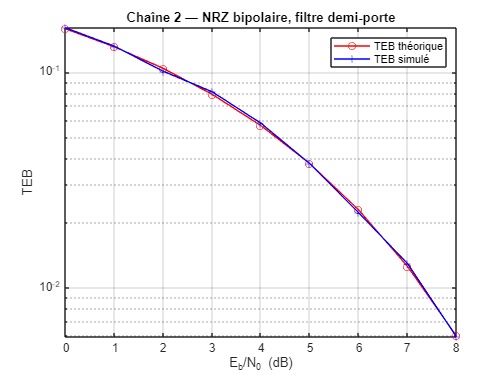


figure('Name', 'Chaîne 2 — NRZ + filtre sous-optimal');
semilogy(tab_Eb_sur_N0_dB, TEB_th_chaine2, 'r-o');
hold on;
semilogy(tab_Eb_sur_N0_dB, TEB_simu_chaine2, 'b-+');
xlabel('E_b/N_0 (dB)');
ylabel('TEB');
title('Chaîne 2 — NRZ bipolaire, filtre demi-porte');
legend('TEB théorique', 'TEB simulé');
grid on;

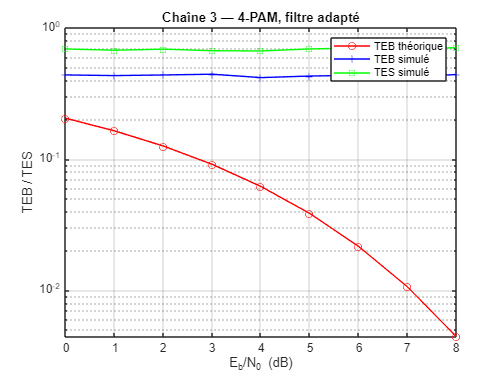


figure('Name', 'Chaîne 3 — 4-PAM + filtre adapté');
semilogy(tab_Eb_sur_N0_dB, TEB_th_chaine3, 'r-o');
hold on;
semilogy(tab_Eb_sur_N0_dB, TEB_simu_chaine3, 'b-+');
semilogy(tab_Eb_sur_N0_dB, TES_simu_chaine3, 'g-s');
xlabel('E_b/N_0 (dB)');
ylabel('TEB / TES');
title('Chaîne 3 — 4-PAM, filtre adapté');
legend('TEB théorique', 'TEB simulé', 'TES simulé');
grid on;

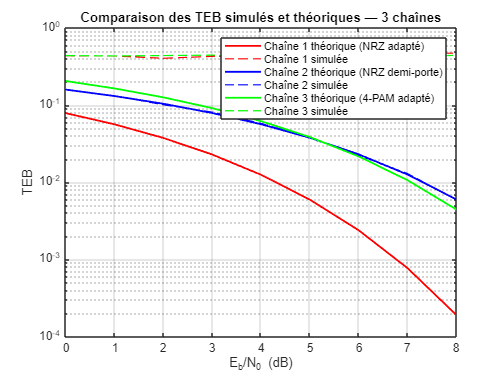



% =========================================================
%  TRACÉ 2 — COMPARAISON des 3 chaînes sur un seul graphe
%  Permet de comparer l'efficacité en puissance :
%  un TEB plus bas pour le même Eb/N0 = meilleure efficacité
% =========================================================

figure('Name', 'Comparaison TEB des 3 chaînes');
semilogy(tab_Eb_sur_N0_dB, TEB_th_chaine1,   'r-',  'LineWidth', 1.5);
hold on;
semilogy(tab_Eb_sur_N0_dB, TEB_simu_chaine1, 'r--', 'LineWidth', 1);
semilogy(tab_Eb_sur_N0_dB, TEB_th_chaine2,   'b-',  'LineWidth', 1.5);
semilogy(tab_Eb_sur_N0_dB, TEB_simu_chaine2, 'b--', 'LineWidth', 1);
semilogy(tab_Eb_sur_N0_dB, TEB_th_chaine3,   'g-',  'LineWidth', 1.5);
semilogy(tab_Eb_sur_N0_dB, TEB_simu_chaine3, 'g--', 'LineWidth', 1);
xlabel('E_b/N_0 (dB)');
ylabel('TEB');
title('Comparaison des TEB simulés et théoriques — 3 chaînes');
legend('Chaîne 1 théorique (NRZ adapté)', ...
       'Chaîne 1 simulée', ...
       'Chaîne 2 théorique (NRZ demi-porte)', ...
       'Chaîne 2 simulée', ...
       'Chaîne 3 théorique (4-PAM adapté)', ...
       'Chaîne 3 simulée');
grid on;

% INTERPRÉTATION :
% - Chaîne 1 < Chaîne 2 en TEB : le filtre adapté est optimal -> meilleure efficacité puissance
% - Chaîne 3 < Chaîne 1 en TEB mais à débit binaire identique, la 4-PAM
%   occupe moins de bande (2 bits/symbole) -> meilleure efficacité spectrale
%   mais moins bonne efficacité puissance (symboles plus proches entre eux)